## Read all data

First extract the data from the H5 file. 

folder = 'G:\My Drive\PRL Group\04 Projects\2 Juan\1 OPUF ANT2 CHIP02\with AuNP\';
%folder = 'C:\Users\Admin\Google Drive\PRL Group\04 Projects\2 Juan\OPUF ANT2 CHIP02\with AuNP\';

%file = 'AllDevices_Au1_Chips02_02_TM.smp';
%file = 'AllDevices_Au1_Chips02_02_TM_user02.smp';
file = 'AllDevices_Au1_Chips02_02_TM_user01_1705.smp';

filename = strcat(folder,file);
struct = h52struct(filename);
meas = struct.project.measurements;

   
   
%index1 = [16, 14, 13, 12;   % Saved Device Numbers
%         2, 3 , 4, 5 ]';    % Index in the measurements list    

Let's check the data extracted from the 1st measurement set.

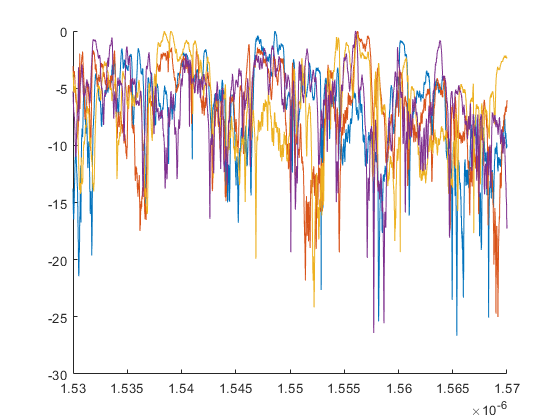

% index1 = [16, 14, 13, 12;   % Saved Device Numbers
%          2, 3 , 4, 5 ]';    % Index in the measurements list  

index1 = [20, 19, 18, 17;   % Saved Device Numbers
         6 , 7, 8,9 ]';    % Index in the measurements list 

m = meas{1}.spectra;
m(:,2) = m(:,2) - max(m(:,2));
lambda = m(:,1);

figure, clf, hold on
%all = zeros(length(m),length(meas));
all_inter = zeros(length(m),4);  

index = sortrows(index1); 
all_inter = zeros(length(m),4);

ind = 0;
for i =index(:,2)'
    ind= ind+1;
    m = meas{i}.spectra;
    m(:,2) = m(:,2) - max(m(:,2)); % Normalization
    all_inter(:,ind) = m(:,2);
    plot(m(:,1), m(:,2));
end
hold off;

## **Statistical Analysis**

We first study the crosscorrelation of the signals, all refered to the first measurement, and create a new set of signals that are shifted in frequecy to maximaize the cross correlation with the reference one, this allows to take into account the possibility of having two difgferent devices that have simialr responses but shifted in frequency, such behviour could be derived from a very small variations of the FSR on resonant cavities that could be essentially tuned using temperature control over the chip. We limit the cross correlation test to a predifned spectral shift.  

First let's the the auto-correlation, several high peaks here would show a periodic behaviour 

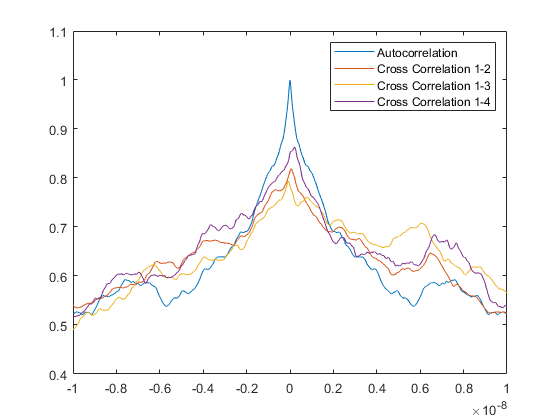

dl = lambda(2)-lambda(1);
xcorr_window = 10e-9; %in meters
xcorr_N = round(xcorr_window/dl);

[c,lags]=xcorr(all_inter(:,1),all_inter(:,1),xcorr_N,'normalized');
plot(lags/xcorr_N*xcorr_window,c);  hold on;

top_shift = 0; bot_shift = 0;
datashift = zeros(size(all_inter));  endi = length(all_inter);
datashift(:,1) = all_inter(:,1);
for i = 2:4
    [c,lags]=xcorr(all_inter(:,1),all_inter(:,i),xcorr_N,'normalized');
    plot(lags/xcorr_N*xcorr_window,c); 
    
    [v,ind]= max(c);
    shift = lags(ind);
    if shift > 0
        datashift(1+shift:endi,i) = all_inter(1:endi-shift,i);
        top_shift = max(shift,top_shift);
    else
        datashift(1:endi+shift,i) = all_inter(1-shift:endi,i);
        bot_shift = min(shift,bot_shift);
    end
end
hold off;
legend({'Autocorrelation','Cross Correlation 1-2','Cross Correlation 1-3',...
        'Cross Correlation 1-4'});


% Crop the shifted data to avoid zero values and the general data to have the same length
datashift = datashift(1+top_shift:endi,:);
c_all = all_inter(1+top_shift:endi,:);
c_lambda = lambda(1+top_shift:endi);

endi = endi-top_shift;
datashift = datashift(1:endi+bot_shift,:);
c_all = c_all(1:endi+bot_shift,:);
c_lambda = c_lambda(1:endi+bot_shift);

We compute the correlation coefficients of the original samples and the shifted ones. These allows to actually test if the samples have become more 'similar' after the spectral shift. Note that although some crosscorrealtions of the shifted response are high, we should still be able to use them as PUFs as long as the following data processing takes into account higher order variations in the signal response.

A = [c_all(:,1) c_all(:,2) c_all(:,3) c_all(:,4)];
R = corrcoef(A)

R =     1.0000    0.2644    0.1410    0.3804
    0.2644    1.0000    0.3038    0.2374
    0.1410    0.3038    1.0000   -0.0344
    0.3804    0.2374   -0.0344    1.0000


    
A = [datashift(:,1) datashift(:,2) datashift(:,3) datashift(:,4)];
R_shift = corrcoef(A)

R_shift =     1.0000    0.2916    0.1819    0.4881
    0.2916    1.0000    0.3682    0.2751
    0.1819    0.3682    1.0000    0.1395
    0.4881    0.2751    0.1395    1.0000



all_data{1} = c_all;
all_data{2} = datashift;


L = 0.15; 
names = {'dev1','dev2','dev3','dev4'};
titles = {'Original Spectrum','Shifted Spectrum'};
    
results = LHD_Compute(c_lambda, all_data, 'all', L, names,titles)
